## Задание 3. Синтез LQG. 

Начальные условия на задание:

A = [5 -7 -5 1;
    -7 5 -1 5;
    -5 -1 5 7;
    1 5 7 5];
mat2tex(A, 1);

\begin{bmatrix}
    5 & -7 & -5 & 1 \\
    -7 & 5 & -1 & 5 \\
    -5 & -1 & 5 & 7 \\
    1 & 5 & 7 & 5 \\
\end{bmatrix}


B = [5 7 1 9; 0 0 0 0]';
mat2tex(B, 1);

\begin{bmatrix}
    5 & 0 \\
    7 & 0 \\
    1 & 0 \\
    9 & 0 \\
\end{bmatrix}


C = [ 0 0 2 2;
     1 1 -1 -1];
mat2tex(C, 1);

\begin{bmatrix}
    0 & 0 & 2 & 2 \\
    1 & 1 & -1 & -1 \\
\end{bmatrix}


D = [0 4; 0 2];
mat2tex(D, 1);

\begin{bmatrix}
    0 & 4 \\
    0 & 2 \\
\end{bmatrix}


**Сделать вывод об управляемости и стабилизируемости системы... ??**

eig(A)

ans =    -8.0000
    4.0000
    8.0000
   16.0000


U = ctrb(A, B);
rank(U)

ans = 4

U = obsv(A, C);
rank(U)

ans = 4

**A --> Управляема + Наблюдаема**

***(Для четных вариантов) Детерминированными сигналами f(t) и ξ(t) (гармонические возмущения).***

**Настройка моделирования**

x0 = [1 1 1 1]';        % plant
x_hat0 = [0 0 0 0]';   % observer
simTimeStart = 0;
simTimeEnd = 15;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';
data.time= time;
modelName = 'model_observer_controller_noise'; 
load_system(modelName);

### Какой-то набор

Выберем значения пар матриц (Q_K, R_K) - для регулятора - выберём рандомные 

Выберем значения пар матриц (Q_L, R_L) - для наблюдателя - выберём рандомные 

QK = diag([5 5 5 5]); RK = diag([20 20]);
QL = diag([1 1 1 1]); RL = diag([10 10]);
mat2tex(QK, 1); mat2tex(RK, 1);

\begin{bmatrix}
    5 & 0 & 0 & 0 \\
    0 & 5 & 0 & 0 \\
    0 & 0 & 5 & 0 \\
    0 & 0 & 0 & 5 \\
\end{bmatrix}
\begin{bmatrix}
    20 & 0 \\
    0 & 20 \\
\end{bmatrix}


mat2tex(QL, 1); mat2tex(RL, 1);

\begin{bmatrix}
    1 & 0 & 0 & 0 \\
    0 & 1 & 0 & 0 \\
    0 & 0 & 1 & 0 \\
    0 & 0 & 0 & 1 \\
\end{bmatrix}
\begin{bmatrix}
    10 & 0 \\
    0 & 10 \\
\end{bmatrix}


%%% Synthesize CTRL %%%
P = are(A, 1*B*RK^-1 *B', QK)

P = 1.0e+03 *

    1.0462   -1.2864    0.5247    0.2844
   -1.2864    1.5968   -0.6739   -0.3640
    0.5247   -0.6739    0.3248    0.1754
    0.2844   -0.3640    0.1754    0.0963


mat2tex(P, 2);

\begin{bmatrix}
    1046.2 & -1286.41 & 524.72 & 284.36 \\
    -1286.41 & 1596.83 & -673.92 & -363.97 \\
    524.72 & -673.92 & 324.78 & 175.43 \\
    284.36 & -363.97 & 175.43 & 96.28 \\
\end{bmatrix}


K = -RK^-1 * B' * P

K =    34.4951  -39.8066    9.5117    4.2002
         0         0         0         0


mat2tex(K, 2);

\begin{bmatrix}
    34.5 & -39.81 & 9.51 & 4.2 \\
    0 & 0 & 0 & 0 \\
\end{bmatrix}


eig(A + B * K) 

ans =   -16.3181
   -8.5011
   -8.0000
   -6.0374


%%% Synthesize OBSV %%%
P = are(A', 1*C'*RL^-1 *C, QL)

P =   489.8476 -400.7708 -109.5563  -20.4802
 -400.7708  410.9099   67.9272   78.0246
 -109.5563   67.9272   41.5570   -0.1818
  -20.4802   78.0246   -0.1818   57.4605


mat2tex(P, 2);

\begin{bmatrix}
    489.85 & -400.77 & -109.56 & -20.48 \\
    -400.77 & 410.91 & 67.93 & 78.02 \\
    -109.56 & 67.93 & 41.56 & -0.18 \\
    -20.48 & 78.02 & -0.18 & 57.46 \\
\end{bmatrix}


L = -P*C'*RL^-1

L =    26.0073  -21.9113
  -29.1904   13.5813
   -8.2750    8.3004
  -11.4557   -0.0266


mat2tex(L, 2);

\begin{bmatrix}
    26.01 & -21.91 \\
    -29.19 & 13.58 \\
    -8.28 & 8.3 \\
    -11.46 & -0.03 \\
\end{bmatrix}


eig(A + L*C)

ans =   -16.0157
   -8.0326
   -8.0048
   -4.0124


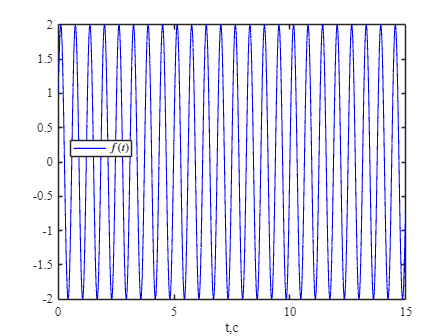

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

f = squeeze(out.f.Data);
xi = out.xi.Data;
% Выбранные f(t) и \xi(t)
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% f(t)
plot(time, f, 'b', 'LineWidth',1);
xlabel('t,c'); ylabel(' ');
title(' ')
legend('$f(t)$','Interpreter','latex','Location','best')
save_file("f2(t)");

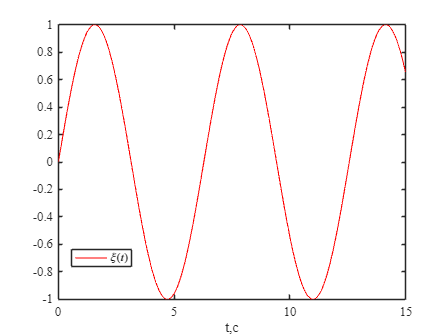


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% xi(t)
plot(time, xi, 'r', 'LineWidth',1);
xlabel('t,c'); ylabel(' ');
title(' ')
legend('$\xi (t)$','Interpreter','latex','Location','best') 
save_file("xi2(t)");

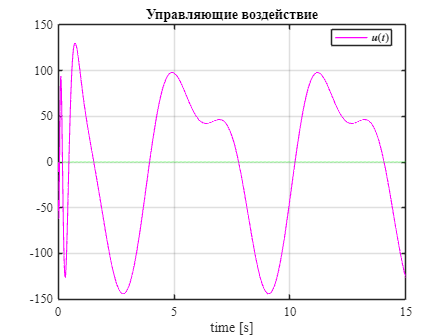

%%%%%%%%%%%%%%%%

u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u(:,1), 'magenta', 'LineWidth', 1.0); hold on; grid on;
plot(time, u(:,2), 'g', 'LineWidth', 1.0);
xlabel('time [s]');
title('Управляющие воздействие')
legend('$u_1(t)$','$u_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("lqg_u1");

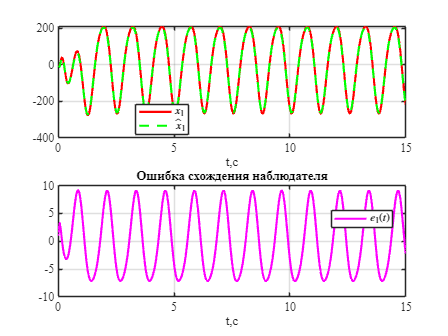


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("lqg1");

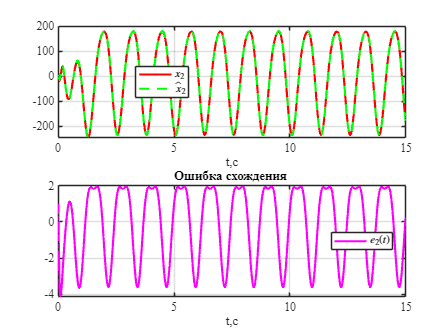

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("lqg2");

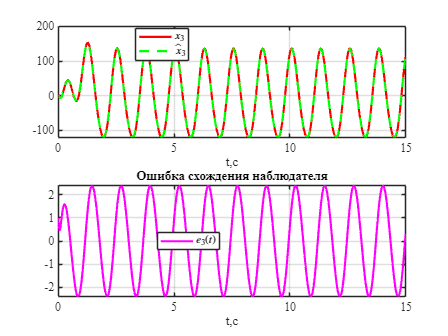

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("lqg3");

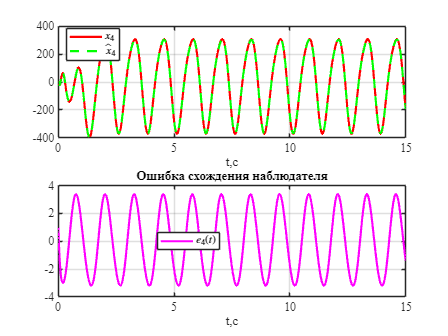

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("lqg4");

%%%%%%%%%%%%%%

### Хороший набор

Выберем значения пар матриц (Q_K, R_K) - для регулятора - выберём  отличные

Выберем значения пар матриц (Q_L, R_L) - для наблюдателя - выберём  отличные

QK = diag([1 1 1 1]); RK = diag([1 1]);
QL = diag([5 5 5 5])^-1; RL = diag([5 5])^-1;

%%% Synthesize CTRL %%%
P = are(A, 1*B*RK^-1 *B', QK)

P =    85.0349 -107.1852   48.0905   25.9090
 -107.1852  136.6381  -63.3247  -33.9655
   48.0905  -63.3247   32.5567   17.2913
   25.9090  -33.9655   17.2913    9.3285


mat2tex(P, 2);

\begin{bmatrix}
    85.03 & -107.19 & 48.09 & 25.91 \\
    -107.19 & 136.64 & -63.32 & -33.97 \\
    48.09 & -63.32 & 32.56 & 17.29 \\
    25.91 & -33.97 & 17.29 & 9.33 \\
\end{bmatrix}


K = -RK^-1 * B' * P

K =    43.8504  -51.5264   14.6420    6.9660
         0         0         0         0


mat2tex(K, 2);

\begin{bmatrix}
    43.85 & -51.53 & 14.64 & 6.97 \\
    0 & 0 & 0 & 0 \\
\end{bmatrix}


eig(A + B * K) 

ans =   -17.8081
  -11.0984
   -8.0000
   -7.1899


%%% Synthesize OBSV %%%
P = are(A', 1*C'*RL^-1 *C, QL)

P =    10.0906   -8.3142   -2.2143   -0.4381
   -8.3142    8.5584    1.3737    1.6097
   -2.2143    1.3737    0.8476   -0.0150
   -0.4381    1.6097   -0.0150    1.1763


mat2tex(P, 2);

\begin{bmatrix}
    10.09 & -8.31 & -2.21 & -0.44 \\
    -8.31 & 8.56 & 1.37 & 1.61 \\
    -2.21 & 1.37 & 0.85 & -0.01 \\
    -0.44 & 1.61 & -0.01 & 1.18 \\
\end{bmatrix}


L = -P*C'*RL^-1

L =    26.5238  -22.1439
  -29.8341   13.6964
   -8.3259    8.3658
  -11.6133   -0.0513


mat2tex(L, 2);

\begin{bmatrix}
    26.52 & -22.14 \\
    -29.83 & 13.7 \\
    -8.33 & 8.37 \\
    -11.61 & -0.05 \\
\end{bmatrix}


eig(A + L*C)

ans =   -16.1598
   -8.3143
   -8.0483
   -4.1180


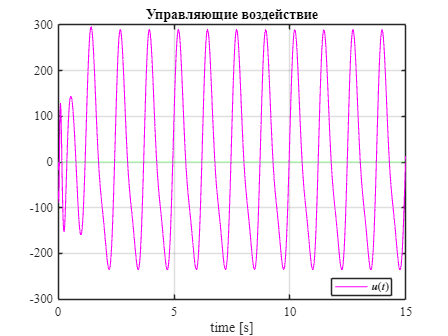

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;


u = out.u.Data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u(:,1), 'magenta', 'LineWidth', 1.0); hold on; grid on;
plot(time, u(:,2), 'g', 'LineWidth', 1.0);
xlabel('time [s]');
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("lqg_u2");

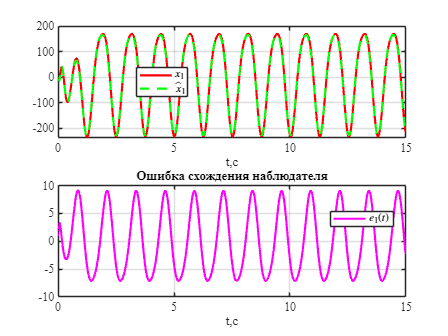


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("lqg5");

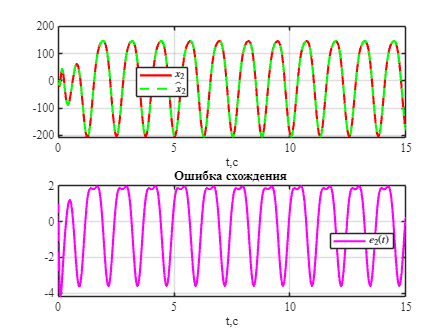

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("lqg6");

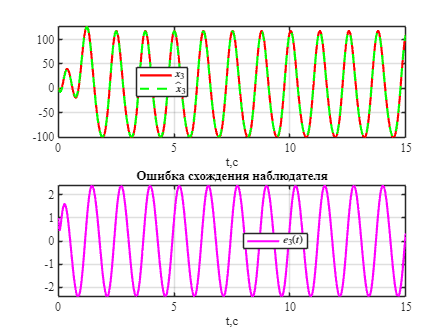

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("lqg7");

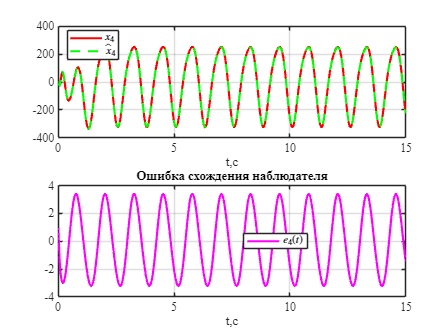

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("lqg8");

%%%%%%%%%%%%%%

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab10\latex10\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end

function latexMatrix = mat2tex(A, precision)
    % Проверка, что A - это матрица
    if ~ismatrix(A)
        error('Input must be a matrix.');
    end
    
    % Проверка, что precision - положительное целое число
    if ~isscalar(precision) || precision < 1 || floor(precision) ~= precision
        error('Precision must be a positive integer.');
    end

    % Начало LaTeX-кода с окружением bmatrix (квадратные скобки)
    lines = ["\begin{bmatrix}"];

    % Формирование строк матрицы
    for i = 1:size(A,1)
        rowElements = strings(1, size(A,2)); % Создаём строку строк для LaTeX
        for j = 1:size(A,2)
            elem = A(i,j);
            if isreal(elem)
                % Округляем число с нужной точностью
                roundedElem = round(elem, precision);
                
                % Проверка, является ли число целым (первые precision знаков после запятой - нули)
                if mod(roundedElem, 1) == 0
                    rowElements(j) = sprintf('%d', roundedElem);
                else
                    % Форматирование дробного числа с нужным precision
                    roundedElem = round(elem, precision);
                    rowElements(j) = regexprep(sprintf('%.*f', precision, roundedElem), '0+$', '');
                    rowElements(j) = regexprep(rowElements(j), '\.$', ''); % Убираем лишнюю точку, если осталась
                end
            else
                % Если элемент комплексный, разбираем его на части
                realPart = real(elem);
                imagPart = imag(elem);

                % Округляем обе части
                realPart = round(realPart, precision);
                imagPart = round(imagPart, precision);

                % Проверка, является ли действительная часть целым числом
                if mod(realPart, 1) == 0
                    realStr = sprintf('%d', realPart);
                else
                    realPart = round(realPart, precision);
                    realStr = regexprep(sprintf('%.*f', precision, realPart), '0+$', '');
                    realStr = regexprep(realStr, '\.$', '');
                end

                % Проверка, является ли мнимая часть целым числом
                if mod(imagPart, 1) == 0
                    imagStr = sprintf('%d', imagPart);
                else
                    imagPart = round(imagPart, precision);
                    imagStr = regexprep(sprintf('%.*f', precision, imagPart), '0+$', '');
                    imagStr = regexprep(imagStr, '\.$', '');
                end

                if realPart == 0
                    % Только мнимая часть
                    rowElements(j) = sprintf('%si', imagStr);
                elseif imagPart == 0
                    % Только действительная часть
                    rowElements(j) = realStr;
                else
                    % Полное комплексное число с правильными знаками
                    signChar = ' + ';
                    if imagPart < 0
                        signChar = ' - ';
                        imagStr = erase(imagStr, '-'); % Убираем минус, так как он уже указан
                    end
                    rowElements(j) = sprintf('%s%s%si', realStr, signChar, imagStr);
                end
            end
        end
        % Объединяем строку с `&` и добавляем её в LaTeX-матрицу
        lines = [lines; "    " + strjoin(rowElements, ' & ') + " \\"]; 
    end

    % Завершение окружения bmatrix
    lines = [lines; "\end{bmatrix}"];

    % Соединяем все строки без добавления `\n`
    latexMatrix = join(lines, newline);

    % Выводим отформатированную строку в командное окно
    disp(latexMatrix);
end
